BIR_st.name='BIR';
BIR_st.lat=58.3886;
BIR_st.lon=8.251944;
BIR_st.alt=219;
BIR_st.env='con';
BIR_st.footp='F';


BIR_rd=read_betsy('BIR_2009_2017', BIR_st.name);

a =    1.0e+03 *
    0.0129    0.0129    0.0129    0.0129    0.0129    0.0129    0.1035    0.0208    0.1035    5.3439       Inf       Inf

S18=read_nasa_ames_ebas('NO0002R.20180101000000.20190527115640.nephelometer..pm10.1y.1h.NO01L_TSI_3563_BIR_dry.NO01L_scat_coef.lev2.nas','\\meteoswiss.ch\mch\pay-prod\Aerosol_actris_trend\data\bir\');

 Reading: \\meteoswiss.ch\mch\pay-prod\Aerosol_actris_trend\data\bir\NO0002R.20180101000000.20190527115640.nephelometer..pm10.1y.1h.NO01L_TSI_3563_BIR_dry.NO01L_scat_coef.lev2.nas


A18=read_nasa_ames_ebas('NO0002R.20180101000000.20190607084148.filter_absorption_photometer.aerosol_absorption_coefficient.pm10.1y.1h.NO01L_Radiance-Research_PSAP-3W_BIR_dry.NO01L_abs_coef_PSAP_v1.lev2.nas','\\meteoswiss.ch\mch\pay-prod\Aerosol_actris_trend\data\bir\');

 Reading: \\meteoswiss.ch\mch\pay-prod\Aerosol_actris_trend\data\bir\NO0002R.20180101000000.20190607084148.filter_absorption_photometer.aerosol_absorption_coefficient.pm10.1y.1h.NO01L_Radiance-Research_PSAP-3W_BIR_dry.NO01L_abs_coef_PSAP_v1.lev2.nas


RH18=read_nasa_ames_ebas('NO0002R.20180101000000.20190527115640.nephelometer.relative_humidity.instrument.1y.1h.NO01L_TSI_3563_BIR_dry.NO01L_scat_coef.lev2.nas','\\meteoswiss.ch\mch\pay-prod\Aerosol_actris_trend\data\bir\');

RHTT=timetable(datetime(datevec(RH18.starttime)));
RHTT.U_S11=RH18.rH;


absTT=timetable(datetime(datevec(A18.starttime)));
absTT.BaB_A11=A18.aerosol_absorption_coefficientB;
absTT.BaG_A11=A18.aerosol_absorption_coefficientG;
absTT.BaR_A11=A18.aerosol_absorption_coefficientR;
flag=A18.flag;
absTT=retime(absTT,'daily',@nanmedian);


scTT=timetable(datetime(datevec(S18.starttime)));
scTT.BsB_S11=S18.aerosol_light_scattering_coefficientB;
scTT.BsG_S11=S18.aerosol_light_scattering_coefficientG;
scTT.BsR_S11=S18.aerosol_light_scattering_coefficientR;
scTT.BbsB_S11=S18.aerosol_light_backscattering_coefficientB;
scTT.BbsG_S11=S18.aerosol_light_backscattering_coefficientG;
scTT.BbsR_S11=S18.aerosol_light_backscattering_coefficientR;

indRH=RHTT.U_S11>50;

scTT.BsB_S11_dry=scTT.BsB_S11;
scTT.BsB_S11_dry(indRH)=NaN;
scTT.BsG_S11_dry=scTT.BsG_S11;
scTT.BsG_S11_dry(indRH)=NaN;
scTT.BsR_S11_dry=scTT.BsR_S11;
scTT.BsR_S11_dry(indRH)=NaN;

scTT.BbsB_S11_dry=scTT.BbsB_S11;
scTT.BbsB_S11_dry(indRH)=NaN;
scTT.BbsG_S11_dry=scTT.BbsG_S11;
scTT.BbsG_S11_dry(indRH)=NaN;
scTT.BbsR_S11_dry=scTT.BbsR_S11;
scTT.BbsR_S11_dry(indRH)=NaN;

flag=S18.flag;
scTT=retime(scTT,'daily',@nanmedian);
RHTT=retime(RHTT,'daily',@nanmedian);

RHTT.T_A11=NaN(length(RHTT.U_S11),1);
RHTT.T_S11=NaN(length(RHTT.U_S11),1);

RHTT.P_S11=NaN(length(RHTT.U_S11),1);
RHTT.Ba1_A11=NaN(length(RHTT.U_S11),1);
RHTT.Ba2_A11=NaN(length(RHTT.U_S11),1);
RHTT.Ba3_A11=NaN(length(RHTT.U_S11),1);


all18=[scTT absTT RHTT];
BIR_rd=[BIR_rd;all18];

datevec(BIR_rd.Time(1))

ans =         2009           7           9           0           0           0

datevec(BIR_rd.Time(end))
 prctile(BIR_rd.U_S11,[5 50 95])

ans =    11.6000   21.1000   39.0425

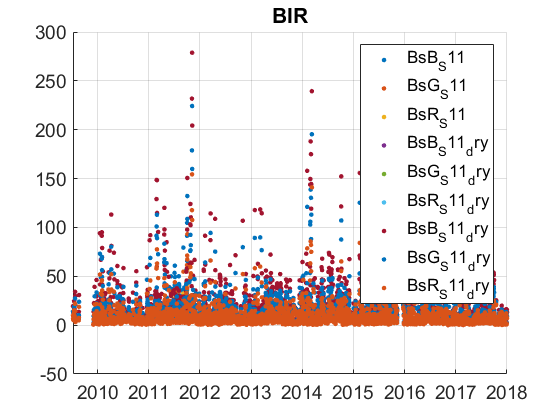

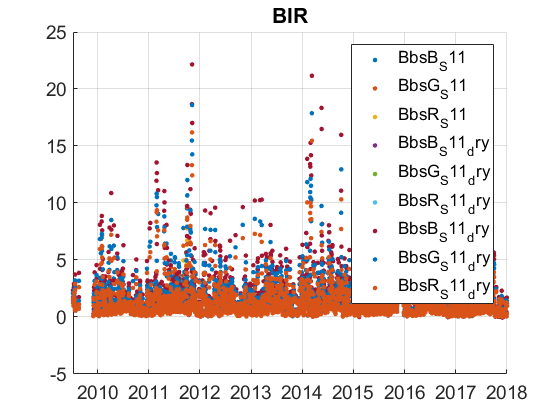

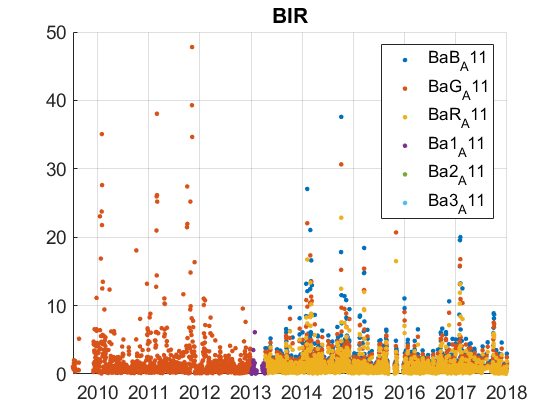

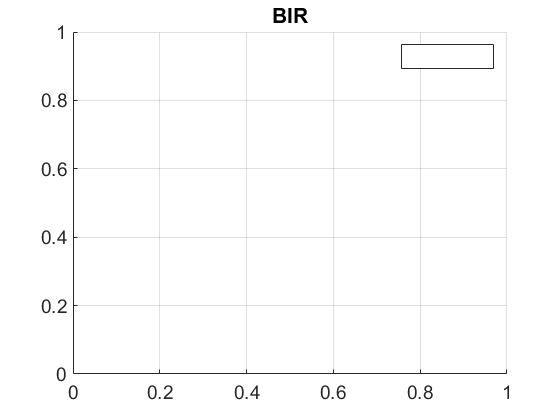

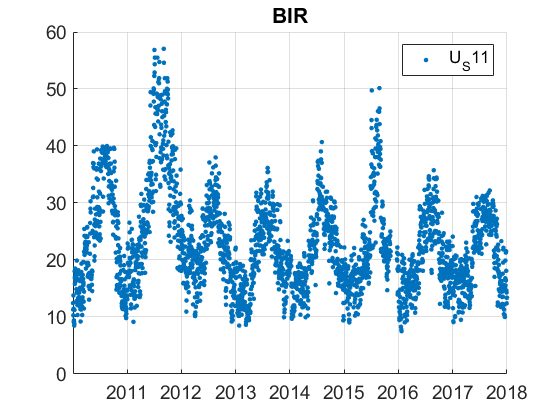

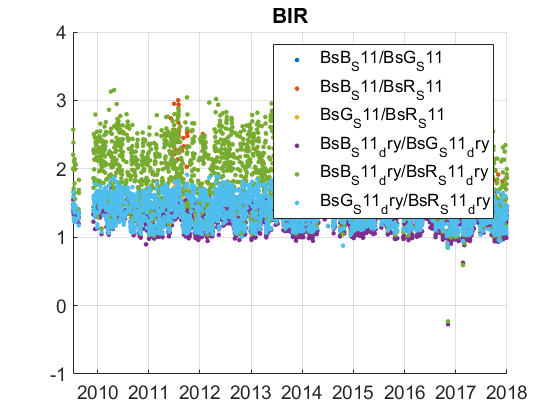

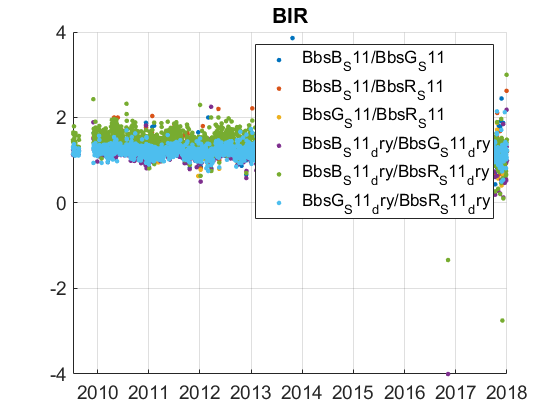

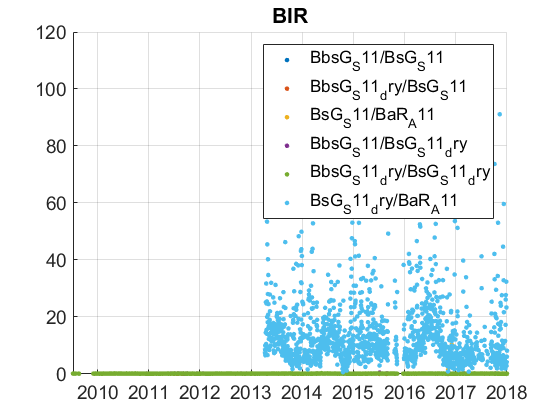

plotFigControl(BIR_rd, BIR_st.name);

% ones size cut
% sc: ok, no clear seasonality, no negatives
% abs: 1 size cut, no clear seasonality, no negatives


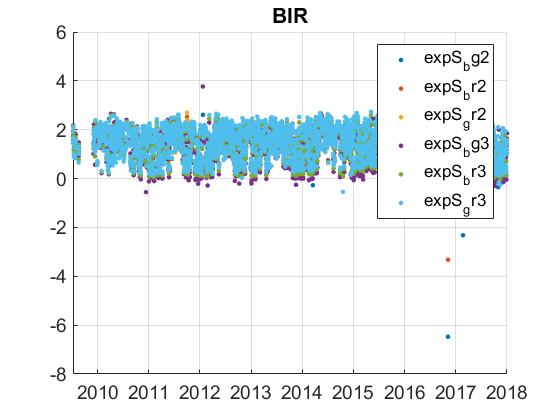

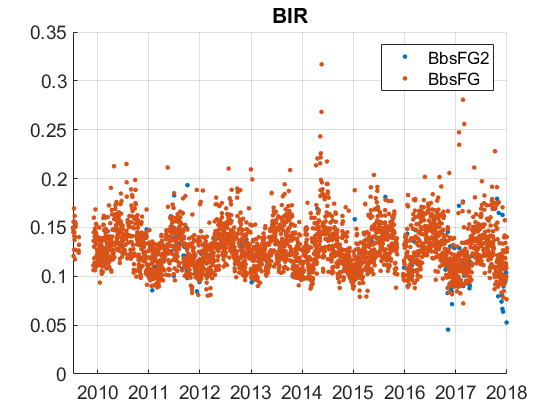

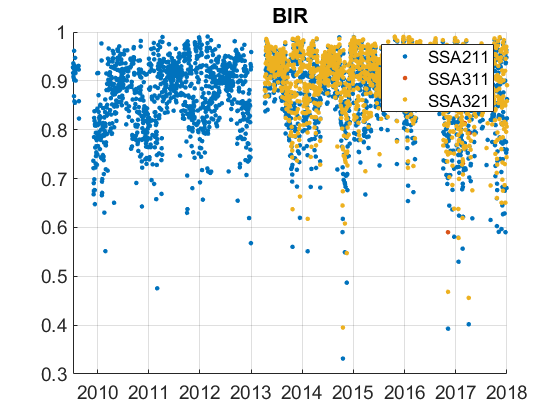

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
BIR_cal=compute_exp_SSA(BIR_rd,lambdaSC, lambdaAE);
plotFigControl_cal(BIR_cal,BIR_st.name);

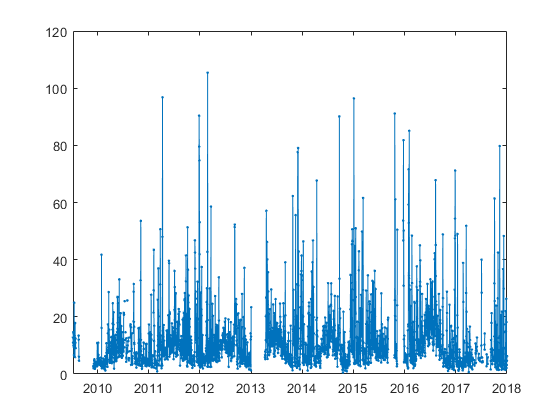

%DO RATION BsG/BaG to see the homogeneity
figure;
plot(BIR_rd.Time, BIR_rd.BsG_S11./BIR_rd.BaG_A11,'.-');

%Questions:
%problems:
%SC: becomes lower since October 2017 (perhaps abs also ??)
% BSP becomes more noisy during winter sin end 2016 (aging?)
%bsp: ratio between 2 w are higher til mid 2010, less visible in sc ratio (just for B/G)
% exp bg min higher in the first mid 2010

%2018 files already downloaded

BIR_tr=BIR_rd;
BIR_tr.y=year(BIR_tr.Time);
% begin at the beginning of a year: 2010 (2017: 8y)
P=timerange('2010-01-01','2019-01-01');
BIR_tr=BIR_tr(P,:);

%no data in Ba2_A11 and Ba3_A11
names=fieldnames(BIR_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_";"N";"Uu";"U1";"Ba2";"Ba3"]) |  contains(names,["Q";"X";"B1_";"G1_";"R1_";"B0_A11";"G0_A11";"R0_A11"]);
N=names(c);
for i=1:length(N)
    BIR_tr.(N{i})=[];
end

%make only one dataset between BaG_A11 and Ba1_A11 ? yes 
BIR_tr.BaG_A11=sum([BIR_tr.BaG_A11 BIR_tr.Ba1_A11],2,'omitnan');
indz=BIR_tr.BaG_A11==0;
BIR_tr.BaG_A11(indz)=NaN;
BIR_tr.Ba1_A11=[];
%PSAP 1w to 3w: compute SSA with green abs + verify the homogeneity
BIR_cal2=compute_exp_SSA(BIR_tr,lambdaSC, lambdaAE);
% absG is longer than absR --> compute SSA with green scat and abs
BIR_cal2.SSAG=BIR_tr.BsG_S11./(BIR_tr.BsG_S11+BIR_tr.BaG_A11);
BIR_tr=outerjoin(BIR_tr, BIR_cal2);

%compute trend only on green
BIR_tr.BsB_S11=[];
BIR_tr.BsB_S11_dry=[];
BIR_tr.BsR_S11=[];
BIR_tr.BsR_S11_dry=[];
BIR_tr.BbsB_S11=[];
BIR_tr.BbsB_S11_dry=[];
BIR_tr.BbsR_S11=[];
BIR_tr.BbsR_S11_dry=[];

BIR_tr.BaB_A11=[];
BIR_tr.BaR_A11=[];

BIR_tr.BbsFG2=[];
BIR_tr.SSA211=[];
BIR_tr.SSA311=[];
BIR_tr.SSA321=[];
BIR_tr.expS_bg3=[];
BIR_tr.expS_br3=[];
BIR_tr.expS_gr3=[];
BIR_tr.expS_br2=[];
BIR_tr.expS_gr2=[];
BIR_tr.expA_br3=[];
BIR_tr.expA_gr3=[];

BIR_result= all_trend_STN(BIR_tr,BIR_st); 
plot_10y_in_two(BIR_result,BIR_st);

BIR_result_D=BIR_result;